clear all;

## Variable b and t1

Ea = 13.4E10; %elastic modulus ceramic
Em = 210E9; %elastic modulus steel

rho_s = 8,050E3; %kg/m^3

rho_s = 8

rho_a = 7.7E3; %kg/m^3

S0 = 3.3; %micrometers
h0 = 2E-3; %m

%constants
h_tot = 80E-3; %mm
t1 = 10E-3; %mm
margin = 1E-3; %mm
d = 40E-3;
w_a = 10E-3;

b0 = 10; %mm
b1 = 150; %mm
bstep = 1;
b = [b0:bstep:b1]*1E-3 ;%m
L1 = length(b);

t1_0 = 1; %mm
t1_1 = 20; %mm
t1_step = 0.1;
t2 = [t1_0:t1_step:t1_1]*1E-3; %m
L2 = length(t2);
[X,Y] = meshgrid(t1_0:t1_step:t1_1,b0:bstep:b1);

%preallocating 
h = zeros(L1,L2); 
L_A = zeros(L1,L2); 
tr = zeros(L1,L2);
S_out = zeros(L1,L2);
m = zeros(L1,L2);
c_g = zeros(L1,L2); 
c_r = zeros(L1,L2); 
c_tot = zeros(L1,L2); 

for i=1:L1
    cb = b(i);
    for j=1:L2
        ct2 = t2(j); %current thickness 
        h(i,j) = h_tot - 2*t1 - 2*margin; %height system
        L_A(i,j) = cb - 2*ct2; %length actuator
        tr(i,j) = (1/12) * (h(i,j)/cb)^2 * (t1 / ct2)^3; %transmission ratio
        S_out(i,j) = ((L_A(i,j)*tr(i,j)/h0) - 1) *S0; %output stroke
        
        
        %computing resulting mass and stiffness
        m(i,j) = 2 * d *(ct2 * h(i,j) + t1* cb) *rho_s + rho_a * L_A(i,j) * w_a^2;
        Ig = t1^3*d;
        Ir = ct2^3*d;
        c_g(i,j) = 192 * Em * Ig / (cb^3);
        c_r(i,j) = 16 * Em * Ir / (cb * h(i,j)^2);
        c_tot(i,j) = 2 * (1/c_g(i,j) + 1/c_r(i,j))^-1;
    end
end


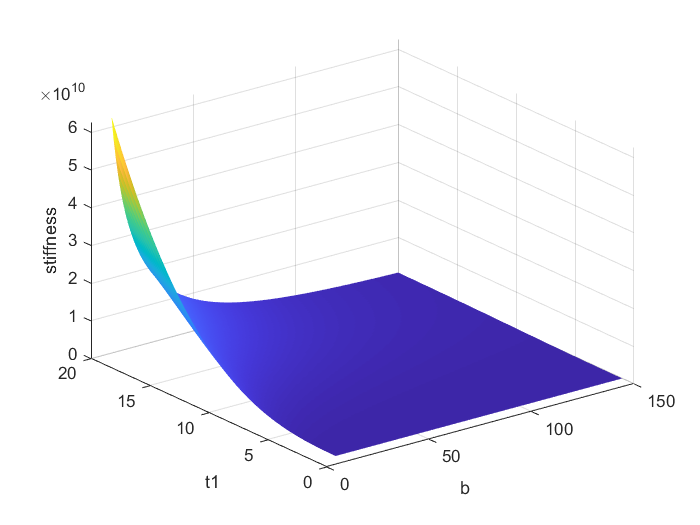

figure 
clf
s1 = surf(Y,X,c_tot);
s1.EdgeColor = 'none';

xlabel("b")
ylabel("t1")
zlabel('stiffness')

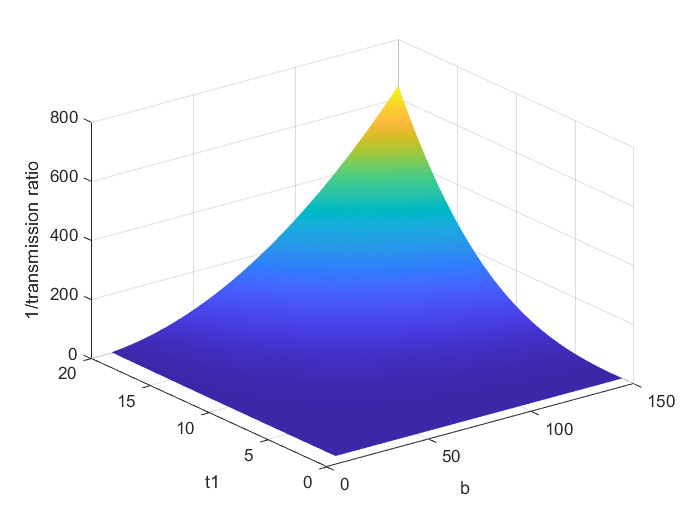


figure 
clf
s1 = surf(Y,X,1./tr);
s1.EdgeColor = 'none';

xlabel("b")
ylabel("t1")
zlabel('1/transmission ratio')

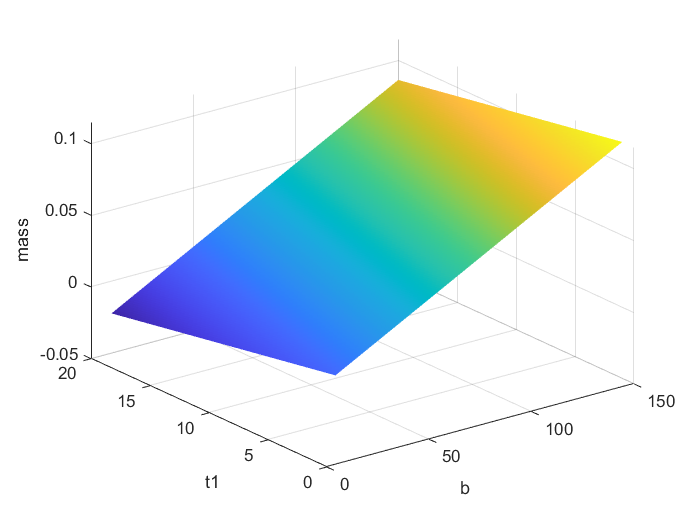


figure 
clf
s1 = surf(Y,X,m);
s1.EdgeColor = 'none';

xlabel("b")
ylabel("t1")
zlabel('mass')

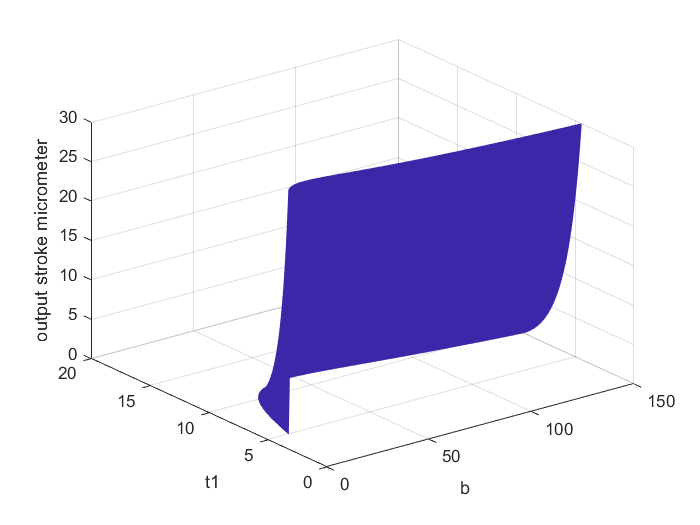



figure 
clf
s1 = surf(Y,X,S_out);
s1.EdgeColor = 'none';

xlabel("b")
ylabel("t1")
zlabel('output stroke micrometer')
zlim([0 30])